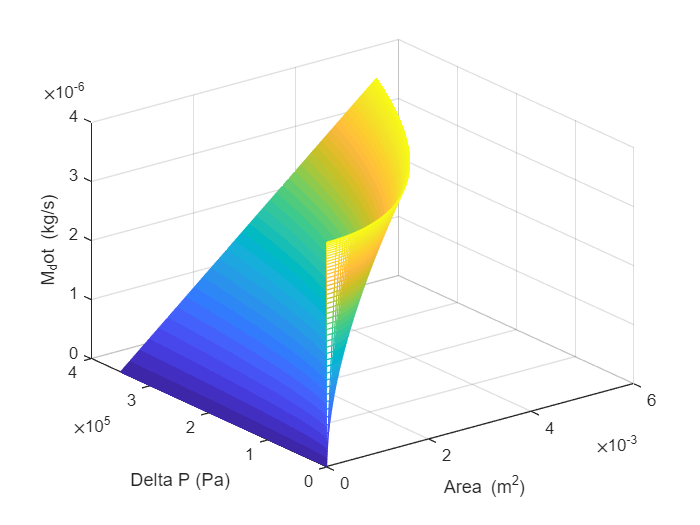

clear; clc;

%---Input Field --------------------------------------------------------%
T_inj = 288;            % Temperature of gas pre injection (K)
gamma = 1.31;           % Specific Heat Ratio
C_d = 0.8;              % Discharge coefficient of the injector
M = 0.016043;           % Molar Mass of the Gas
delt_P = 0:500:350000;   % Change in pressure (Pa)

P_2 = 620528.2;          % Combustion Pressure (Pa)

%-----------------------------------------------------------------------%

d_0 = 2.2*10e-4;         % Seat Orifice Diameter (m)
theta = 0.4366271598;    % Needle Cone Angle (Rad)
h_max = (d_0*(1-sqrt(1-cos(theta/2))))/sin(theta);
h = 0:0.0001:h_max;

%----Calculation Field--------------------------------------------------%
P_1 = P_2 + delt_P;

P_crit = (2/(gamma+1))^(gamma/(gamma-1));   % Calculate critical Pressure
R = 8.314/M;                                % Specific gas constant 

%----Chocked Flow Determination and Calculaiton-------------------------%
for i = 1:length(delt_P)
    P_ratio(i) = P_2/P_1(i);
    if P_ratio(i) <= P_crit
        Flowischoked = "Choked";
    else 
        Flowischoked = "Not Choked";
    end

    for j = 1:length(h)
        A(i,j) = pi*h(j)*sin(theta/2)*(d_0-h(j)/2*sin(theta));
        if Flowischoked == "Choked"
            m_dot(i,j) = C_d*A(i,j)*P_1(i)*sqrt(gamma/(R*T_inj))*(2/(gamma+1))^((gamma+1)/(2*(gamma-1)));
        else
            m_dot(i,j) = C_d*A(i,j)*P_1(i)*sqrt((2*gamma)/(R*T_inj*(gamma-1))*(P_ratio(i)^(2/gamma)-P_ratio(i)^((gamma+1)/gamma)));
        end
    end
end

mesh(m_dot,delt_P,A)
xlabel("Area (m^2)");
ylabel("Delta P (Pa)");
zlabel("M_dot (kg/s)");